# Replace Title Text in Placeholder

Add a title slide to a presentation and then replace the slide placeholders for the title and subtitle with your title and subtitle text.

Import the PPT package so that you do not have to use long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*

 Create a presentation.

ppt = Presentation("myTextBoxPlaceholderPresentation.pptx");
open(ppt);

Add a title slide.

slide = add(ppt,"Title Slide");

Use the `find` method of the slide object to find the placeholder object that has the name `Title`.

titlePlaceholderObj = find(slide,"Title")

The `find` method returns an `mlreportgen.ppt.TextBoxPlaceholder` object.

Replace the placeholder content with the title text.

replace(titlePlaceholderObj(1),"My Title");

Find the placeholder object for the subtitle. 

subtitlePlaceholderObj = find(slide,"Subtitle")

The placeholder object for the subtitle is also an `mlreportgen.ppt.TextBoxPlaceholder` object.

Replace the placeholder content with the text for the subtitle.

replace(subtitlePlaceholderObj(1),"My Subtitle");

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the title slide in the generated presentation:

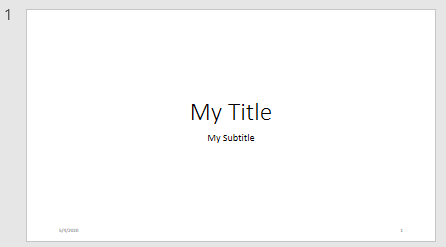

*Copyright 2020 The MathWorks, Inc.*